clear; clc; close all

% Riproducibilità
rng(42);

# Obiettivo

Lo scopo di questo progetto è creare una CNN che identifichi quale "tipo" di sfocatura è stata applicata all'immagine. Con "tipo" in questo contesto si intende il kernel con cui è stata convoluta l'immagine, nel dettaglio sono stati presi in considerazione i seguenti:

%Lista kernel normalizzati
disp('Box_3 =')

Box_3 =


disp(ones(3,3)/9)

    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('Box_5 =')

Box_5 =


disp(ones(5,5)/25)

    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('Gauss_3 =')

Gauss_3 =


disp([
    1 2 1;
    2 4 2;
    1 2 1
]/16)

    0.0625    0.1250    0.0625
    0.1250    0.2500    0.1250
    0.0625    0.1250    0.0625



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('Gauss_5 =')

Gauss_5 =


disp([
    1  4  6  4  1;
    4 16 24 16  4;
    6 24 36 24  6;
    4 16 24 16  4;
    1  4  6  4  1
]/256)

    0.0039    0.0156    0.0234    0.0156    0.0039
    0.0156    0.0625    0.0938    0.0625    0.0156
    0.0234    0.0938    0.1406    0.0938    0.0234
    0.0156    0.0625    0.0938    0.0625    0.0156
    0.0039    0.0156    0.0234    0.0156    0.0039



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('Circ_5 =')

Circ_5 =


disp([
    0 0 1 0 0;
    0 1 1 1 0;
    1 1 1 1 1;
    0 1 1 1 0;
    0 0 1 0 0
]/13)

         0         0    0.0769         0         0
         0    0.0769    0.0769    0.0769         0
    0.0769    0.0769    0.0769    0.0769    0.0769
         0    0.0769    0.0769    0.0769         0
         0         0    0.0769         0         0



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('Cross_5 =')

Cross_5 =


disp([
    0 0 1 0 0;
    0 0 1 0 0;
    1 1 1 1 1;
    0 0 1 0 0;
    0 0 1 0 0
]/9)

         0         0    0.1111         0         0
         0         0    0.1111         0         0
    0.1111    0.1111    0.1111    0.1111    0.1111
         0         0    0.1111         0         0
         0         0    0.1111         0         0



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('D =')

D =


disp(eye(5)/5)

    0.2000         0         0         0         0
         0    0.2000         0         0         0
         0         0    0.2000         0         0
         0         0         0    0.2000         0
         0         0         0         0    0.2000



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('H =')

H =


disp([
    0 0 0 0 0;
    0 0 0 0 0;
    1 1 1 1 1;
    0 0 0 0 0;
    0 0 0 0 0
]/5)

         0         0         0         0         0
         0         0         0         0         0
    0.2000    0.2000    0.2000    0.2000    0.2000
         0         0         0         0         0
         0         0         0         0         0



fprintf("---------------------------------------------------\n");

---------------------------------------------------



disp('V =')

V =


disp([
    0 0 1 0 0;
    0 0 1 0 0;
    0 0 1 0 0;
    0 0 1 0 0;
    0 0 1 0 0
]/5)

         0         0    0.2000         0         0
         0         0    0.2000         0         0
         0         0    0.2000         0         0
         0         0    0.2000         0         0
         0         0    0.2000         0         0



fprintf("---------------------------------------------------\n");

---------------------------------------------------


fprintf("In aggiunta:")

In aggiunta:

fprintf("Median_5: restituisce la mediana della finestra 5x5");

Median_5: restituisce la mediana della finestra 5x5

fprintf("Originale: nessuna modifica all'immagine originale");

Originale: nessuna modifica all'immagine originale

# EDA

Come dataset è stato scelto "[COCO 2017 Unlabeled Images](https://cocodataset.org/#download)" data la grande varietà di soggetti al suo interno. Inoltre per avere un'idea della capacità di generalizzare del modello è stato creato un secondo dataset combinando "[Sea Animals Image Dataset🌊](https://www.kaggle.com/datasets/vencerlanz09/sea-animals-image-dataste)" e "[Count Coins Image dataset](https://www.kaggle.com/datasets/balabaskar/count-coins-image-dataset)" (mix di animali marini e monete).

Essendo le immagini delle semplici fotografie è stato necessario creare uno script che facesse la convoluzione in modo da applicare la sfocatura artificiale. Tuttavia alcune immagini risultavano già sfocate ad occhio nudo e per evitare che facessero sorgere problematiche varie sono state rimosse basandosi sul procedimento iillustrato in "[Blur detection with OpenCV](https://pyimagesearch.com/2015/09/07/blur-detection-with-opencv/)". In breve consiste nell'effettuare la convoluzione con un kernel che rileva i bordi e calcolare la varianza della matrice risultante, più il valore è alto più l'immagine è nitida. Basta poi scegliere una soglia sotto la quale le immagini vengono scartate. 

(N.B. Questo metodo funziona ma non è perfetto)

A grandi linee l'elaborazione di una singola immagine è:

- Apri immagine in scala di grigi

- Se troppo piccola/sfocata passa alla successiva

- Applica la convoluzione con un kernel casuale

- Ritaglia una porzione di dimensione 224x224

- Salva risultato

Qualche informazione:

% Caricamento immagini
path = fullfile('Dataset', 'Da usare');
imgs = imageDatastore(path, "IncludeSubfolders", true, "LabelSource", "foldernames");

path2 = fullfile('Dataset', 'Da usare1');
imgs2 = imageDatastore(path2, "IncludeSubfolders", true, "LabelSource", "foldernames");

fprintf("Dataset principale");

Dataset principale

fprintf('Numero totale di immagini: %d\n', numel(imgs.Labels));

Numero totale di immagini: 60000


fprintf('Training: %d\n', numel(imgs.Labels) * 0.7);

Training: 42000


fprintf('Validazione: %d\n', numel(imgs.Labels) * 0.15);

Validazione: 9000


fprintf('Test: %d\n\n', numel(imgs.Labels) * 0.15);

Test: 9000



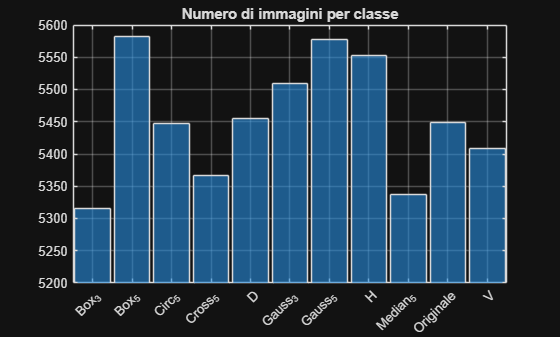


% Immagini per classe
figure;

countcats(imgs.Labels);
histogram(imgs.Labels);

title('Numero di immagini per classe');
ylim([5200, 5600]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

xtickangle(45);

grid on;

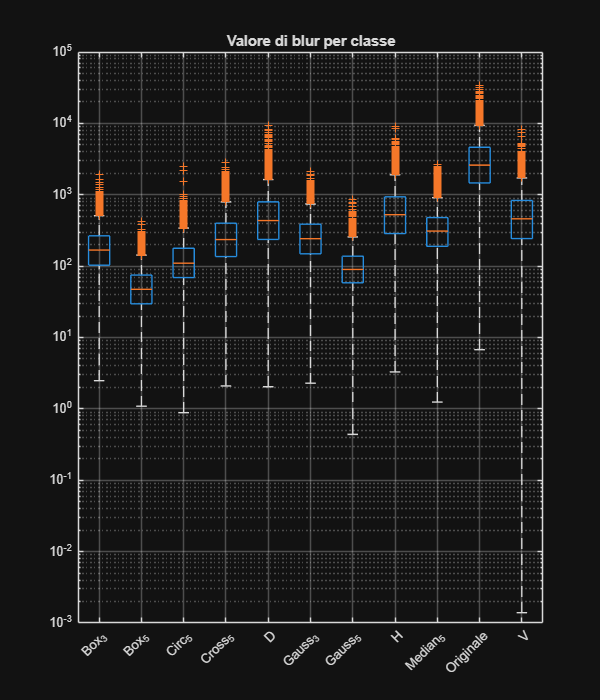



% Boxplot del laplaciano per classe
figure;

T = readtable(fullfile(path, 'blur_scores.csv'), ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

T.kernel = categorical(T.kernel);
T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));

boxplot(T.blur_score_dopo, T.kernel);
set(gcf, 'Position', [100, 100, 600, 700]);
set(gca,'YScale', 'log')

ax = gca;
ax.TickLabelInterpreter = 'tex';

title('Valore di blur per classe');

xtickangle(45);
grid on;


fprintf("I valori sull'asse delle ordinate sono calcolati con il metodo visto prima ma \n" + ...
    "dopo aver applicato la sfocatura.");

I valori sull'asse delle ordinate sono calcolati con il metodo visto prima ma 
dopo aver applicato la sfocatura.



fprintf('%s\n', repmat(' ', 1, 80));

% Altro dataset

fprintf('Secondo dataset');

Secondo dataset

fprintf('Numero totale di immagini: %d\n', numel(imgs2.Labels));

Numero totale di immagini: 1360


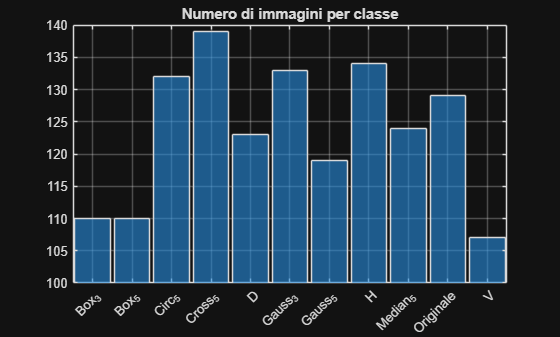


% Immagini per classe
figure;

countcats(imgs2.Labels);
histogram(imgs2.Labels);

title('Numero di immagini per classe');
ylim([100, 140]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

xtickangle(45);

grid on;

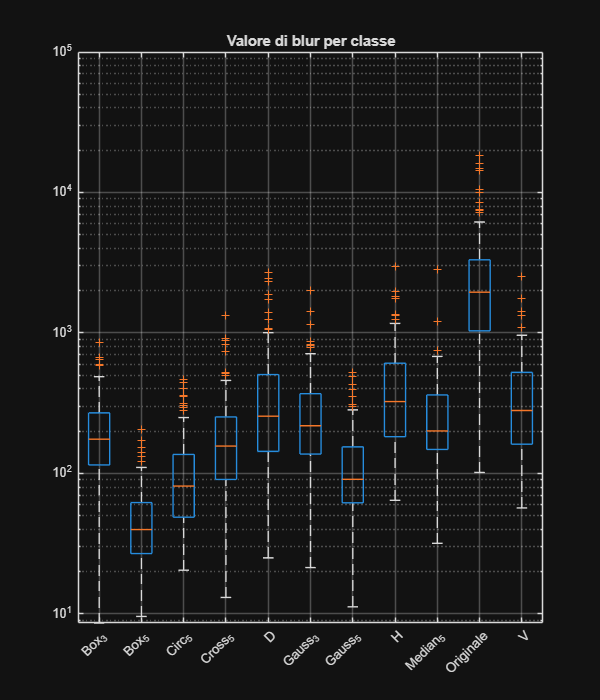



% Boxplot del laplaciano per classe
figure;

T = readtable(fullfile(path2, 'blur_scores.csv'), ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

T.kernel = categorical(T.kernel);
T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));

boxplot(T.blur_score_dopo, T.kernel);
set(gcf, 'Position', [100, 100, 600, 700]);
set(gca,'YScale', 'log')

ax = gca;
ax.TickLabelInterpreter = 'tex';

title('Valore di blur per classe');

xtickangle(45);
grid on;

# Struttura della rete

La struttura della CNN in sé è semplice:

% Carica la cnn addestrata
S = load('rete11.mat');

%Mostra struttura
layers = S.net.Layers;

for i = 1:numel(layers)

    L = layers(i);

    fprintf('\n====================================\n');
    fprintf('Layer %d: %s\n', i, L.Name);
    fprintf('Tipo: %s\n', class(L));

    switch class(L)

        case 'nnet.cnn.layer.ImageInputLayer'
            fprintf('Input: %s\n', mat2str(L.InputSize));

        case 'nnet.cnn.layer.Convolution2DLayer'
            fprintf('Grandezza filtro: %s\n', mat2str(L.FilterSize));
            fprintf('Numero filtri: %d\n', L.NumFilters);
            fprintf('Stride: %s\n', mat2str(L.Stride));

        case 'nnet.cnn.layer.BatchNormalizationLayer'
            fprintf('Numero canali: %d\n', L.NumChannels);

        case 'nnet.cnn.layer.MaxPooling2DLayer'
            fprintf('Grandezza pooling: %s\n', mat2str(L.PoolSize));
            fprintf('Stride: %s\n', mat2str(L.Stride));

        case 'nnet.cnn.layer.DropoutLayer'
            fprintf('Probabilità: %.2f\n', L.Probability);

        case 'nnet.cnn.layer.FullyConnectedLayer'
            fprintf('Numero neuroni: %d\n', L.OutputSize);

    end
end

Layer 1: imageinput


Tipo: nnet.cnn.layer.ImageInputLayer


Input: [224 224 1]


Layer 2: conv_1


Tipo: nnet.cnn.layer.Convolution2DLayer


Grandezza filtro: [5 5]


Numero filtri: 8


Stride: [1 1]


Layer 3: batchnorm_1


Tipo: nnet.cnn.layer.BatchNormalizationLayer


Numero canali: 8


Layer 4: relu_1


Tipo: nnet.cnn.layer.ReLULayer


Layer 5: conv_2


Tipo: nnet.cnn.layer.Convolution2DLayer


Grandezza filtro: [3 3]


Numero filtri: 16


Stride: [1 1]


Layer 6: batchnorm_2


Tipo: nnet.cnn.layer.BatchNormalizationLayer


Numero canali: 16


Layer 7: relu_2


Tipo: nnet.cnn.layer.ReLULayer


Layer 8: maxpool_1


Tipo: nnet.cnn.layer.MaxPooling2DLayer


Grandezza pooling: [2 2]


Stride: [2 2]


Layer 9: conv_3


Tipo: nnet.cnn.layer.Convolution2DLayer


Grandezza filtro: [3 3]


Numero filtri: 32


Stride: [1 1]


Layer 10: batchnorm_3


Tipo: nnet.cnn.layer.BatchNormalizationLayer


Numero canali: 32


Layer 11: relu_3


Tipo: nnet.cnn.layer.ReLULayer


Layer 12: maxpool_2


Tipo: nnet.cnn.layer.MaxPooling2DLayer


Grandezza pooling: [2 2]


Stride: [2 2]


Layer 13: dropout


Tipo: nnet.cnn.layer.DropoutLayer


Probabilità: 0.30


Layer 14: fc


Tipo: nnet.cnn.layer.FullyConnectedLayer


Numero neuroni: 11


Layer 15: softmax


Tipo: nnet.cnn.layer.SoftmaxLayer


Layer 16: classoutput


Tipo: nnet.cnn.layer.ClassificationOutputLayer


Per quanto riguarda le opzioni di addestramento:

opts = S.options;

fprintf('Ottimizzatore: %s\n', erase(class(opts),'nnet.cnn.TrainingOptions'));

Ottimizzatore: SGDM


fprintf('Learning rate iniziale: %.1e\n', opts.InitialLearnRate);

Learning rate iniziale: 3.0e-04


fprintf('Learn. rate schedule: %s\n', opts.LearnRateSchedule);

Learn. rate schedule: piecewise


fprintf('Learn. rate drop factor: %.2f\n', opts.LearnRateDropFactor);

Learn. rate drop factor: 0.10


fprintf('Learn. rate drop period: %d epoche\n', opts.LearnRateDropPeriod);

Learn. rate drop period: 15 epoche



fprintf('Numero max epoche: %d\n', opts.MaxEpochs);

Numero max epoche: 30


fprintf('Dimensioni mini-batch: %d\n', opts.MiniBatchSize);

Dimensioni mini-batch: 32



fprintf('Shuffle dati: %s\n', opts.Shuffle);

Shuffle dati: every-epoch


fprintf('Frequenza di validazione: %d iterazioni\n', opts.ValidationFrequency);

Frequenza di validazione: 438 iterazioni


fprintf('Pazienza: %d', opts.ValidationPatience);

Pazienza: 5


fprintf('Ambiente di esecuzione: %s\n', opts.ExecutionEnvironment);

Ambiente di esecuzione: cpu


Queste sono la struttura e le opzioni che hanno portato al modello con le percentuali migliori, nei vari tentativi antecedenti sono emersi diversi elementi non adatti all'obiettivo:

- Rete con troppi strati convoluzionali

- Layer convoluzionali con troppi filtri o con filtri troppo grandi

- Average Pooling

- Min Pooling

- Entrambi i Global Pooling

- Funzioni diverse dalla ReLU o da una sua variante

- Ottimizzatore ADAM

# Esempio di funzionamento

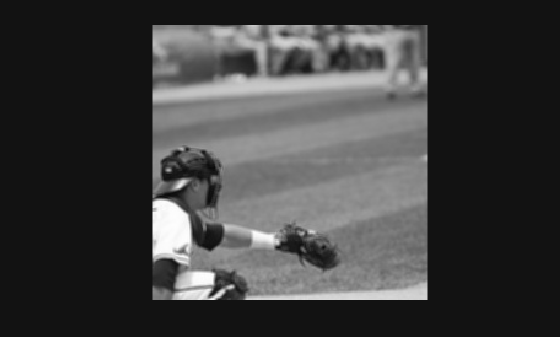

% Servono solo quelle di test
[~ , imgsTemp] = splitEachLabel(imgs, 0.7, "randomized");
[~, imgsTest] = splitEachLabel(imgsTemp, 0.5, "randomized");

I = readimage(imgsTest, 1);

figure
imshow(I)

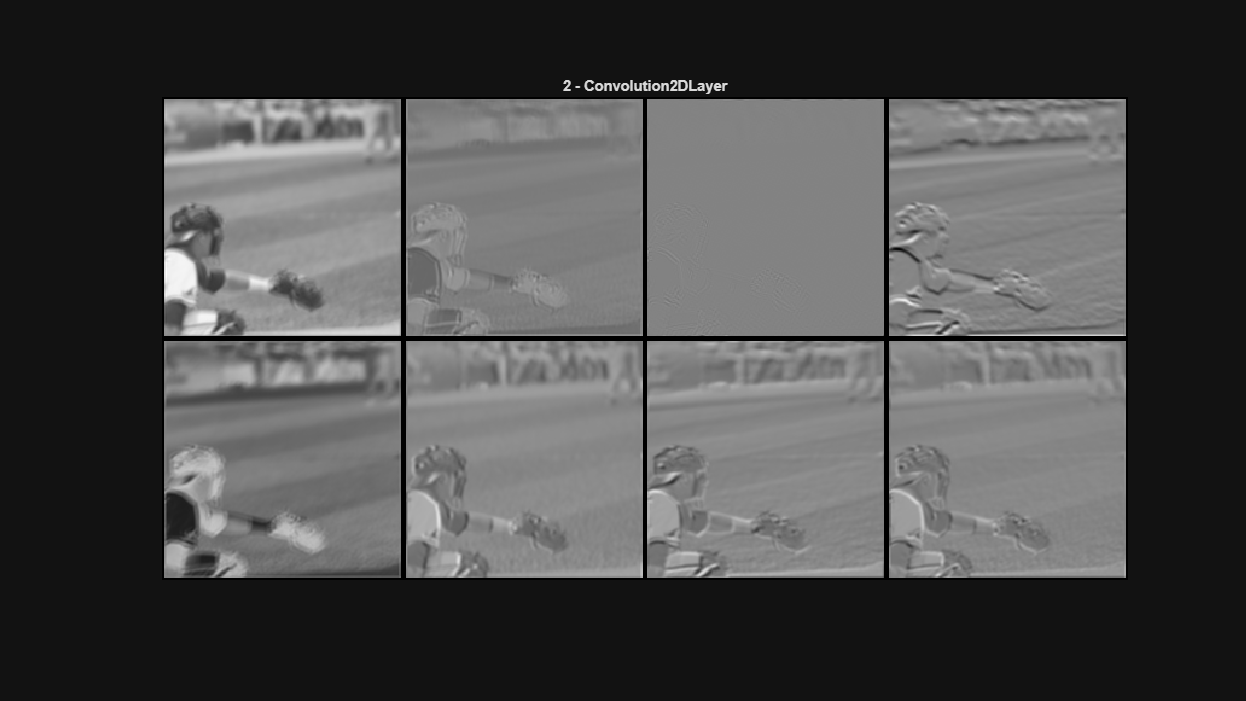

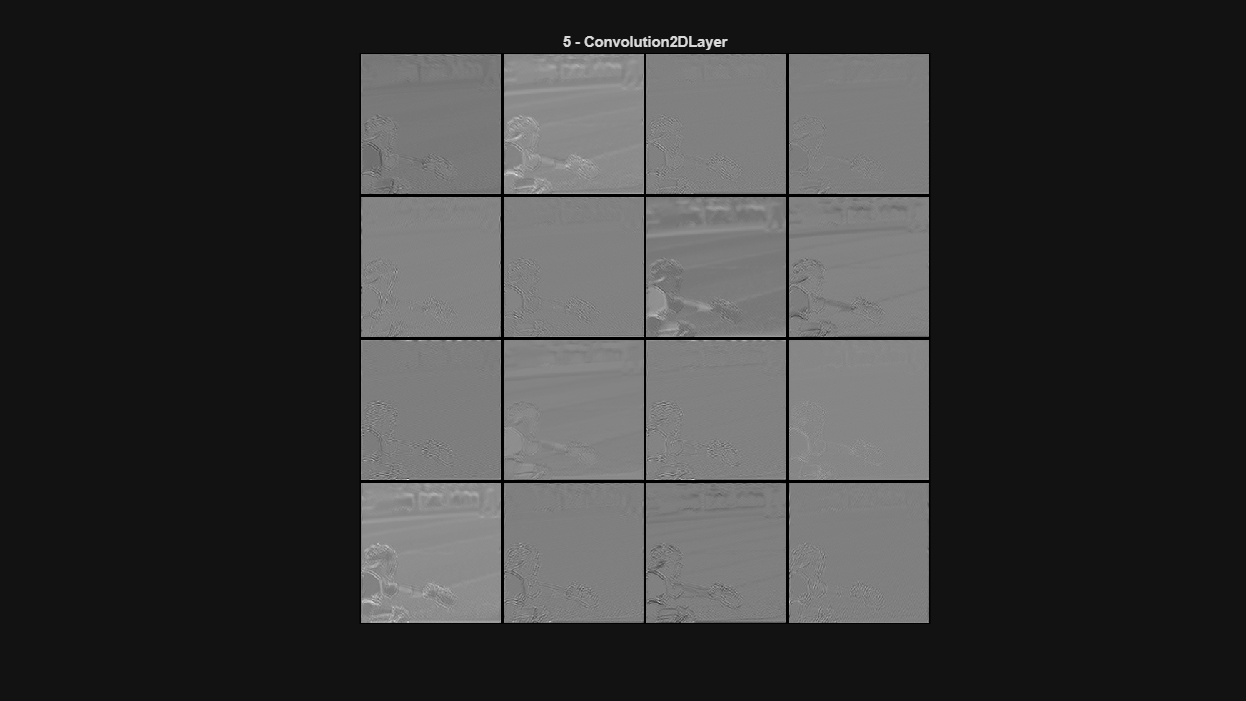

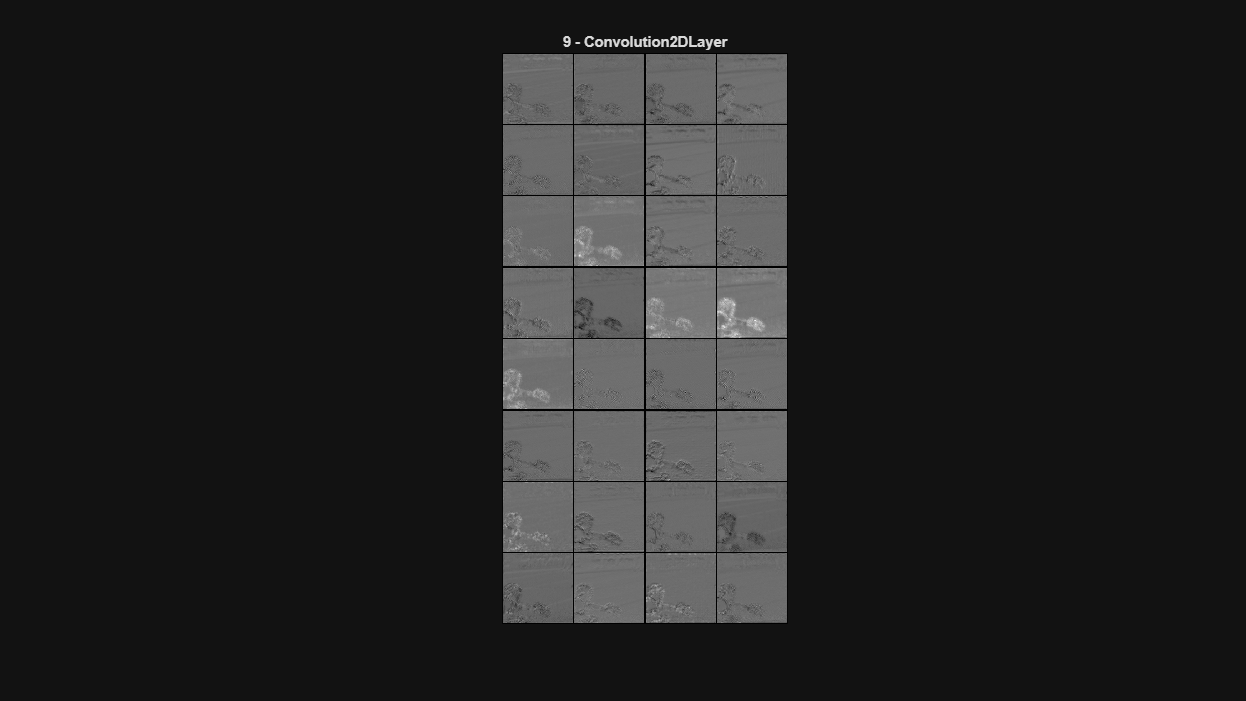

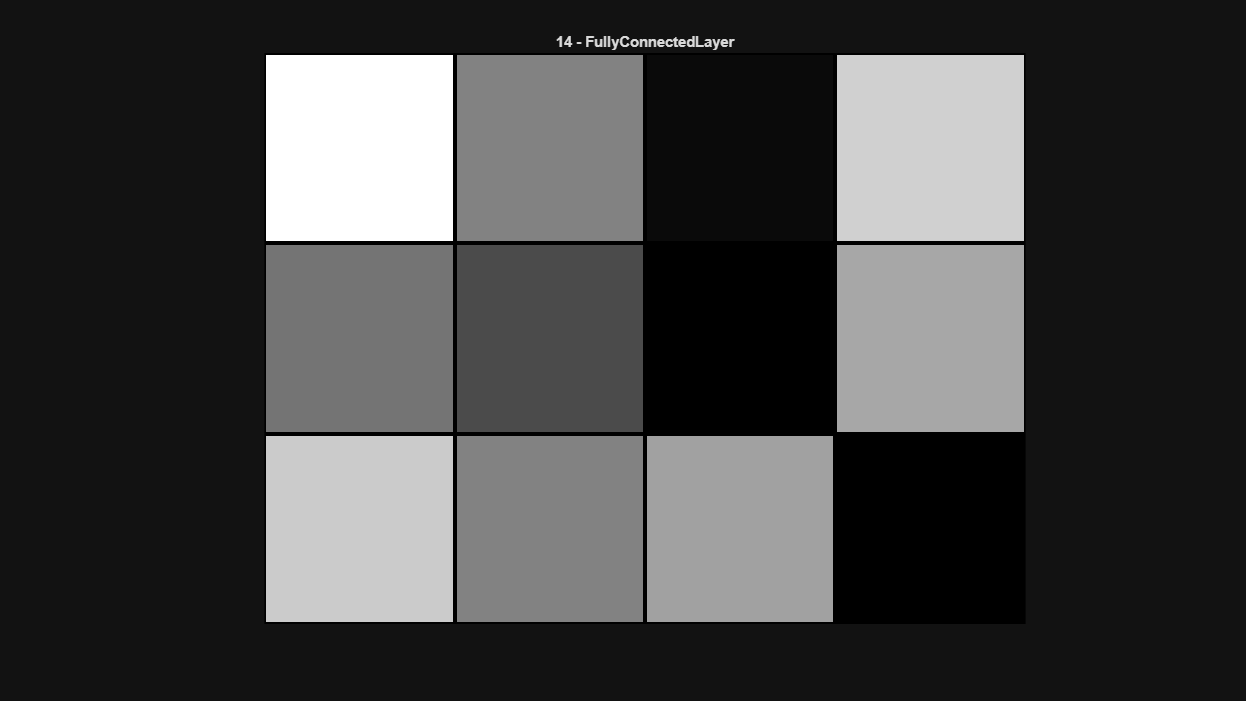

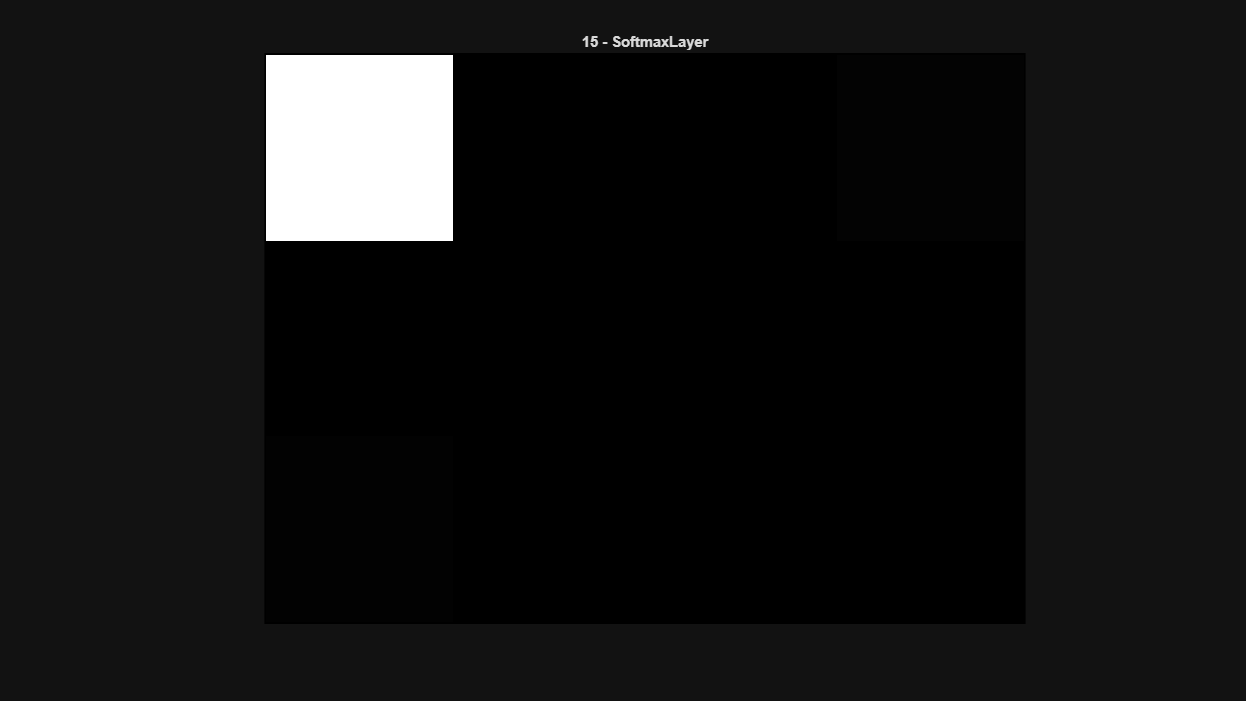


for i = 1:numel(layers)

    tipo = class(layers(i));

    if contains(tipo, 'Convolution2DLayer') || ...
       contains(tipo, 'FullyConnectedLayer') || ...
       contains(tipo, 'SoftmaxLayer') || ...
       contains(tipo, 'ClassificationOutputLayer')

        A = activations(S.net, I, i, 'OutputAs', 'channels');

        figure('Units','normalized','OuterPosition',[0 0 1 1])

        if ndims(A)==3
            montage(mat2gray(A), ...
                'Size',[NaN 4], ...
                'ThumbnailSize',[196 196], ...
                'BorderSize',[2 2]);

        elseif isvector(A)
            bar(A);
            grid on;
            xlabel('Neurone');
            ylabel('Attivazione');

        end

        title(sprintf('%d - %s', ...
            i, erase(tipo,'nnet.cnn.layer.')))

    end
end

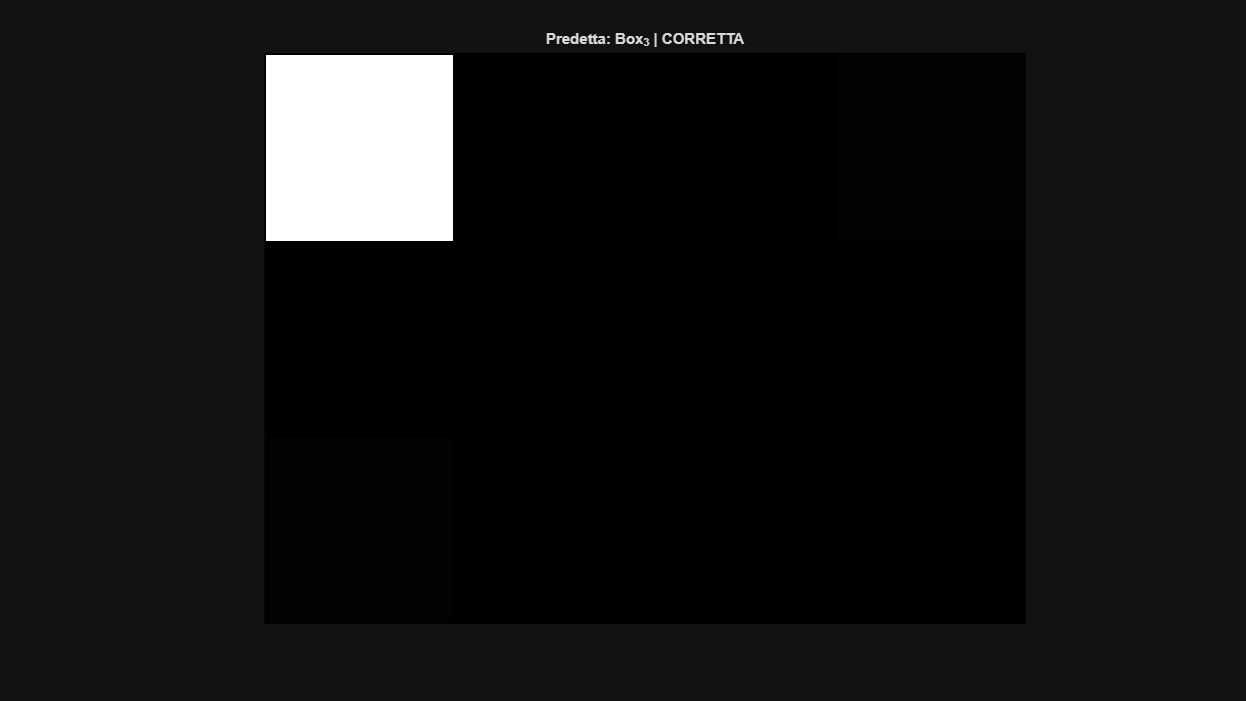


% Classe predetta
YPred = classify(S.net, I);

% Classe reale
YTrue = imgsTest.Labels(1);

% Confronto
if YPred == YTrue
    risultato = 'CORRETTA';
else
    risultato = 'ERRATA';
end

title(sprintf('Predetta: %s | %s', ...
    string(YPred), risultato))

# Metriche

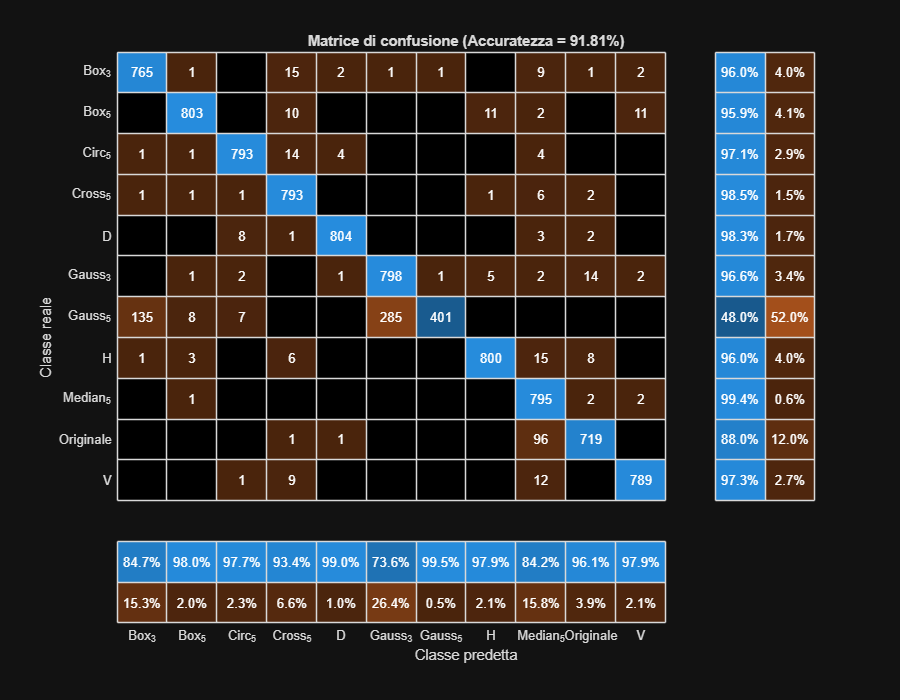

% Matrice di confusione
YPred = classify(S.net, imgsTest);
YTest = imgsTest.Labels;

accuracy = mean(YPred == YTest);

figure('Position', [100 100 900 700]);
cm = confusionchart(YTest, YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Classe predetta';
cm.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione (Accuratezza = %.2f%%)', accuracy * 100));


%% Metriche di valutazione
C = confusionmat(YTest, YPred);

TP = diag(C);
FP = sum(C,1)' - TP;
FN = sum(C,2) - TP;
TN = sum(C(:)) - TP - FP - FN;

precision  = TP ./ (TP + FP);
recall     = TP ./ (TP + FN);
specificity = TN ./ (TN + FP);
f1         = 2 * (precision .* recall) ./ (precision + recall);

% Media delle metriche
precisionMean  = mean(precision, 'omitnan');
recallMean     = mean(recall, 'omitnan');
specificityMean = mean(specificity, 'omitnan');
f1Mean         = mean(f1, 'omitnan');

fprintf('Precisione media  : %.2f%%\n', precisionMean*100);

Precisione media  : 92.92%


fprintf('Recall medio      : %.2f%%\n', recallMean*100);

Recall medio      : 91.92%


fprintf('Specificità media : %.2f%%\n', specificityMean*100);

Specificità media : 99.18%


fprintf('F1-Score medio    : %.2f%%\n\n', f1Mean*100);

F1-Score medio    : 91.34%




% Metriche per classe
T = table(categories(YTest), specificity, f1, ...
    'VariableNames', {'Classe', 'Specificità', 'F1-Score'});

disp(T);

       Classe        Specificità    F1-Score
    _____________    ___________    ________

    {'Box_3'    }      0.98317          0.9 
    {'Box_5'    }      0.99804      0.96981 
    {'Circ_5'   }      0.99768       0.9736 
    {'Cross_5'  }      0.99316      0.95889 
    {'D'        }      0.99902       0.9865 
    {'Gauss_3'  }        0.965       0.8356 
    {'Gauss_5'  }      0.99975       0.6473 
    {'H'        }      0.99792       0.9697 
    {'Median_5' }      0.98182       0.9117 
    {'Originale'}      0.99645      0.91885 
    {'V'        }      0.99792      0.97588 




fprintf('%s\n', repmat(' ', 1, 80));

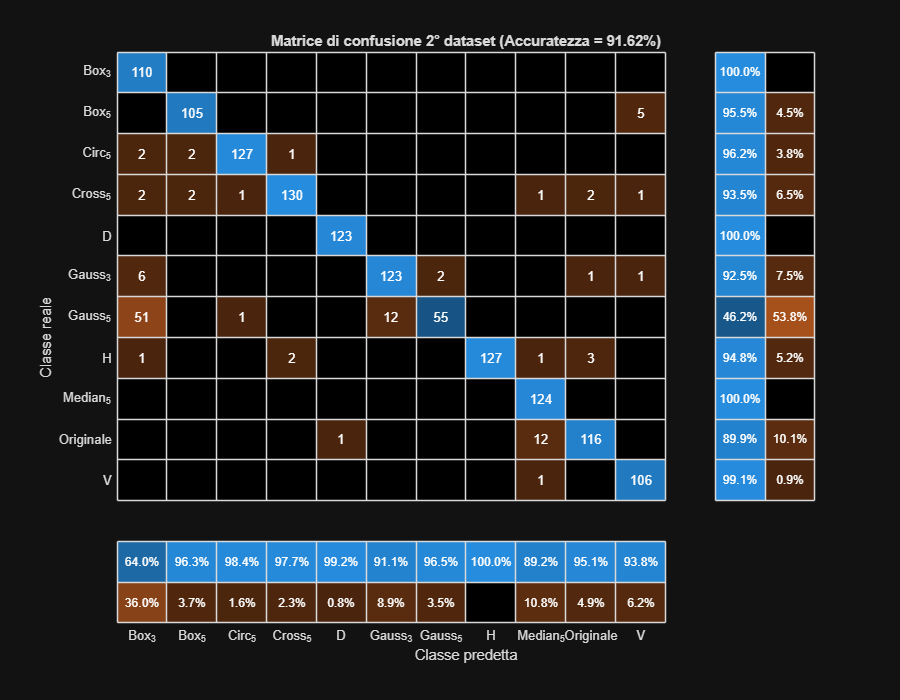


% Secondo dataset
YPred2 = classify(S.net, imgs2);
YTest2 = imgs2.Labels;

accuracy2 = mean(YPred2 == YTest2);

figure('Position', [100 100 900 700]);
cm2 = confusionchart(YTest2, YPred2);
cm2.RowSummary = 'row-normalized';
cm2.ColumnSummary = 'column-normalized';
cm2.XLabel = 'Classe predetta';
cm2.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione 2° dataset (Accuratezza = %.2f%%)', accuracy2 * 100));


%% Metriche di valutazione 2
C = confusionmat(YTest2, YPred2);

TP = diag(C);
FP = sum(C,1)' - TP;
FN = sum(C,2) - TP;
TN = sum(C(:)) - TP - FP - FN;

precision  = TP ./ (TP + FP);
recall     = TP ./ (TP + FN);
specificity = TN ./ (TN + FP);
f1         = 2 * (precision .* recall) ./ (precision + recall);

% Media delle metriche
precisionMean  = mean(precision, 'omitnan');
recallMean     = mean(recall, 'omitnan');
specificityMean = mean(specificity, 'omitnan');
f1Mean         = mean(f1, 'omitnan');

fprintf('Precisione media  : %.2f%%\n', precisionMean*100);

Precisione media  : 92.85%


fprintf('Recall medio      : %.2f%%\n', recallMean*100);

Recall medio      : 91.61%


fprintf('Specificità media : %.2f%%\n', specificityMean*100);

Specificità media : 99.17%


fprintf('F1-Score medio    : %.2f%%\n\n', f1Mean*100);

F1-Score medio    : 91.01%




% Metriche per classe
T = table(categories(YTest2), specificity, f1, ...
    'VariableNames', {'Classe', 'Specificità', 'F1-Score'});

disp(T);

       Classe        Specificità    F1-Score
    _____________    ___________    ________

    {'Box_3'    }       0.9504      0.78014 
    {'Box_5'    }       0.9968       0.9589 
    {'Circ_5'   }      0.99837      0.97318 
    {'Cross_5'  }      0.99754      0.95588 
    {'D'        }      0.99919      0.99595 
    {'Gauss_3'  }      0.99022      0.91791 
    {'Gauss_5'  }      0.99839        0.625 
    {'H'        }            1      0.97318 
    {'Median_5' }      0.98786      0.94297 
    {'Originale'}      0.99513       0.9243 
    {'V'        }      0.99441      0.96364 



Dalle matrici si nota come la versione 3x3 della Box e i 2 Gauss tendono ad essere confusi molto spesso. Questo è probabilmente dovuto al fatto che producono risultati molto simili, quasi indistinguibili ad occhio nudo. 

Una cosa simile succede anche per Median_5, in particolare viene scambiata per un'immagine originale un numero non indifferente di volte. Qui però potrebbe dipendere dalla mediana stessa che se viene calcolata su un'immagine abbastanza nitida potrebbe avere un effetto minimo.

Trascurando quest'ultima (che non è una convoluzione in senso stretto) e constatando che tutte le varie architetture provate presentano il medesimo problema si può dire con una certa confidenza che questa problematica derivi dal problema in sé. Ipotesi che viene ulteriormente avvalorata dal fatto che quasi tutte le altre percentuali sono ben oltre il 95%.